clear
clc

system("g++ ./src/FiniteDifferences.cpp " + ...
    "-O2 -o ./src/FiniteDifferences.exe -Wall");
DV_th_1 = 3.262699 - 1.635605;
DV_th_2 = 2.939627 - 1.961261;

ind = 1;
N_range = 100 : 100 : 2000;
for N = N_range
    N
    system(".\src\FiniteDifferences.exe " + string(N));
    M = N;
    
    v1.x = round((500 - 68.75)/1000 * N);
    v1.y = round(500/1000 * N);
    v2.x = round((500 + 68.75)/1000 * N);
    v2.y = round(500/1000 * N);
    
    v3.x = round((500 - 68.75)/1000 * N);
    v3.y = round((500 + 100)/1000 * N);
    v4.x = round((500 + 68.75)/1000 * N);
    v4.y = round((500 + 100)/1000 * N);
    
    x = load("x.txt");
 
    %DV(ind) = abs(phi(v1.y,v1.x) - phi(v2.y,v2.x));
    DV1(ind) = abs(x(v1.x + N * (v1.y - 1)) - x(v2.x + N * (v2.y - 1))); %#ok [V]
    DV2(ind) = abs(x(v3.x + N * (v3.y - 1)) - x(v4.x + N * (v4.y - 1))); %#ok [V]
    ind = ind + 1;
end

N = 100

N = 200

N = 300

N = 400

N = 500

N = 600

N = 700

N = 800

N = 900

N = 1000

N = 1100

N = 1200

N = 1300

N = 1400

N = 1500

N = 1600

N = 1700

N = 1800

N = 1900

N = 2000

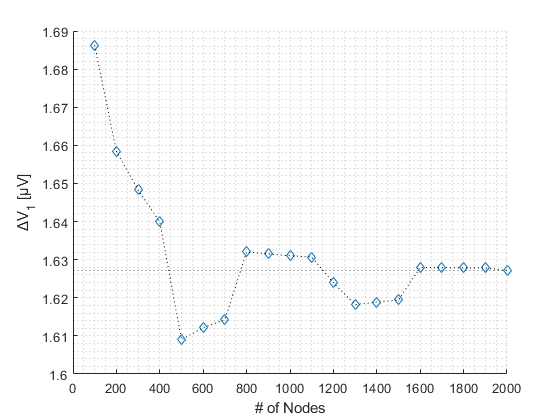

figure();
scatter(N_range,DV1 * 1e6,'d');
hold on
plot(N_range,DV1 * 1e6,'k:');
hold off
grid minor
xlabel('# of Nodes')
ylabel('ΔV_1 [μV]')
yline(DV_th_1,':');

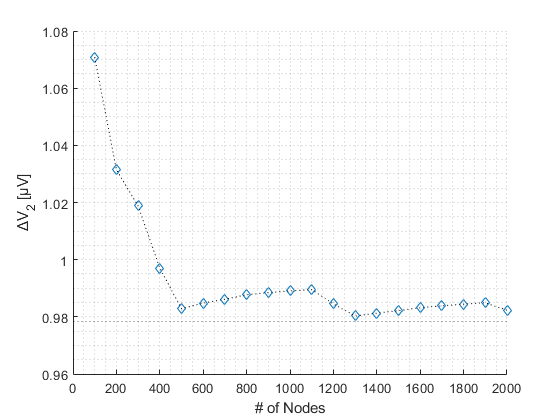


figure();
scatter(N_range,DV2 * 1e6,'d');
hold on
plot(N_range,DV2 * 1e6,'k:');
hold off
grid minor
xlabel('# of Nodes')
ylabel('ΔV_2 [μV]')
yline(DV_th_2,':');

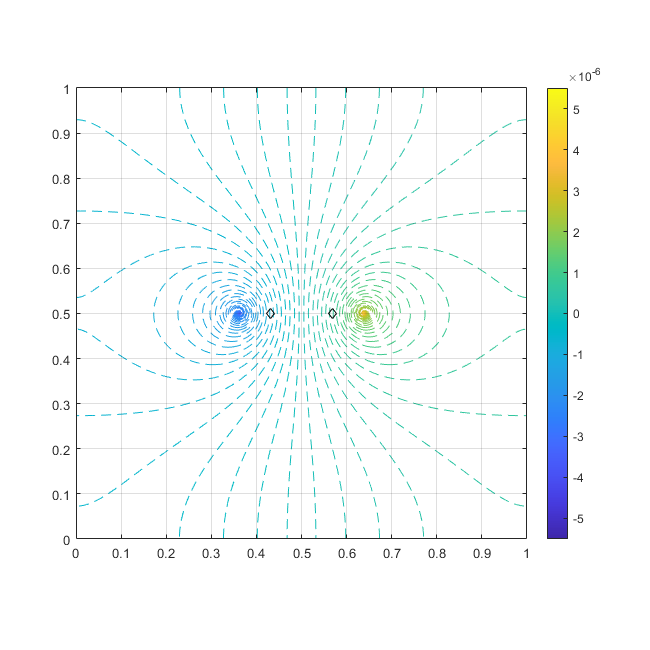

phi = zeros(M,N);
for i = 1:N
    for j = 1:M
        phi(j,i) = x(i + N * (j-1));
    end
end

psi = zeros(M,N);
for i = 3:N
    for j = 3:M-1
        psi(j,i) = 1/3 * (4*psi(j-1,i) - psi(j-2,i) + (3*phi(j,i) - 4*phi(j,i-1) + phi(j,i-2)));
    end
end

figure("Position",[0,0,650,650]);
X_range = linspace(0,1,size(phi,2));
Y_range = linspace(0,1,size(phi,1));
Dx = X_range(2) - X_range(1);
Dy = Y_range(2) - Y_range(1);
contour(X_range,Y_range,phi,100,'LineStyle',"--")
hold on
% contour(psi,100,'LineStyle',":", ...
%     'LineColor','k')
scatter(Dx*v1.x,Dy*v1.y,'kd')
scatter(Dx*v2.x,Dy*v2.y,'kd')
xticks(X_range(1) : X_range(end)/10 : X_range(end))
yticks(Y_range(1) : Y_range(end)/10 : Y_range(end))
hold off
grid on
axis equal
colorbar()


% mesh(psi)
% view([-75 10])

save("aaaaa.mat")